## **Problemă de optimizare neconstrânsă în învățarea aprofundată - Regresie**

clear
A=readmatrix("Real estate valuation data set.xlsx");
A=(A-mean(A))./std(A);
A_train=A(1:331,2:7);
A_test=A(332:414,2:7);
e_train=A(1:331,8);
e_test=A(332:414,8);
[N_train,n]=size(A_train);
N_test=size(A_test,1);

A_train=[A_train ones(N_train,1)];
A_test=[A_test ones(N_test,1)];
m=10;


Am folosit baza de date [Real Estate Valuation - UCI Machine Learning Repository](https://archive.ics.uci.edu/dataset/477/real+estate+valuation+data+set), care prezintă 414 instanțe cu câte 6 caracteristici fiecare. Antrenarea rețelei neuronale cu m=10 neuroni intermediari are rolul de a estima costul unei case per unitate de suprafață (10000 New Taiwan Dollar/Ping) din New Taipei City, Taiwan. Datele le-am împărțit 80% (331) în date de antrenare, iar restul de 20% (83) în date pentru testare.

În calcularea derivatelor de ordin I si II, am alăturat parametrii optimi X și x într-un singur vector de lungime ((n+2)*m,1).

## `Metoda Gradient:`

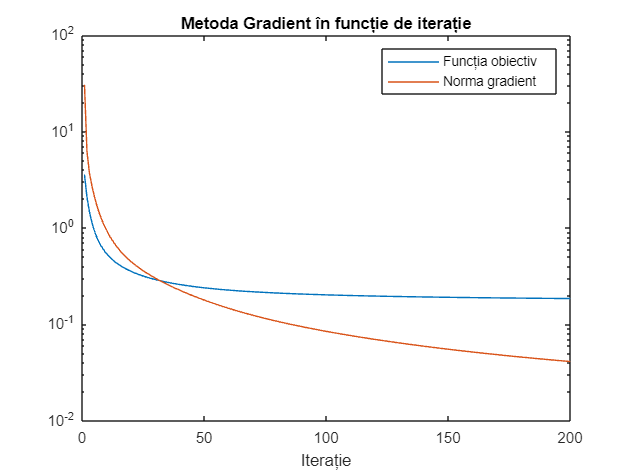

iter=0;
iterMax=200;
eps=0.01; 

Xx=randn((n+2)*m,1);

tic
while iter==0 || (fOb(iter)>eps && iter<iterMax)
    gradient=gradNum(e_train,A_train,Xx,m);
    alfaK=fminbnd(@(alfa) L(e_train,A_train,Xx-alfa*gradient,m),0,0.05);
    Xx=Xx-alfaK*gradient;
    iter=iter+1;
    normG(iter)=norm(gradient);
    fOb(iter)=L(e_train,A_train,Xx,m);
    v(iter)=toc;
end

semilogy(1:iter,fOb)
hold on
semilogy(1:iter,normG)
xlabel("Iterație")
legend("Funcția obiectiv","Norma gradient")
title("Metoda Gradient în funcție de iterație")
hold off

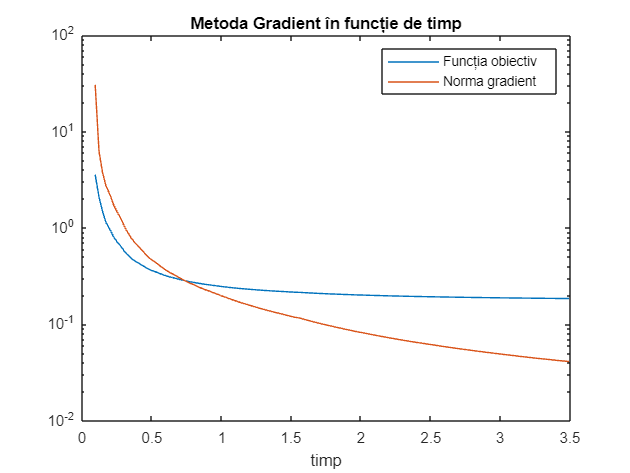


semilogy(v,fOb)
hold on 
semilogy(v,normG)
xlabel("timp")
legend("Funcția obiectiv","Norma gradient")
title("Metoda Gradient în funcție de timp")
hold off


X=reshape(Xx(1:(n+1)*m),m,n+1)';
x=Xx((n+1)*m+1:(n+2)*m);

Scor de antrenare:

y_train=g(A_train*X)*x;
R2_train=1-(norm(e_train-y_train))^2/(norm(e_train-mean(e_train)))^2

R2_train = 0.6445

Scor de testare:

y_test=g(A_test*X)*x;
R2_test=1-(norm(e_test-y_test))^2/(norm(e_test-mean(e_test)))^2

R2_test = 0.6050

Gradientul funcției l-am calculat sub formă numerică, care a dus la rularea foarte rapidă a algoritmului (3,5s). 

Se observă cum funcția obiectiv converge undeva între 10^0 si 10^(-1), iar norma gradient scade în continuare, chiar sub 10^(-1).

Scorul R2 indică o proporție de 64% din date care sunt explicate de model, un rezultat ok.

## `Metoda Newton:`

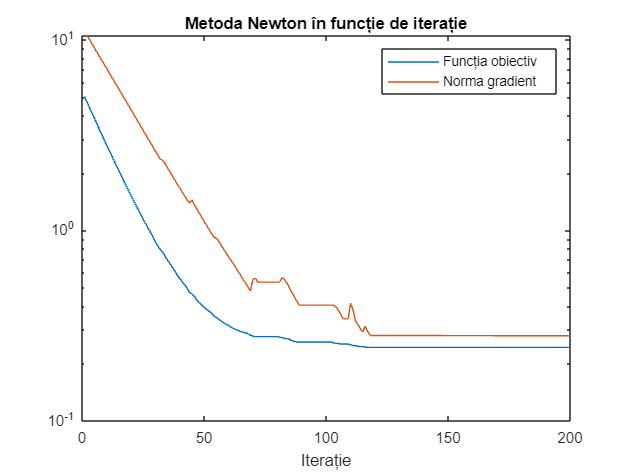

iter=0;
iterMax=200;
eps=0.01; 

Xx=randn((n+2)*m,1);

tic
while iter==0 || (fOb(iter)>eps && iter<iterMax)
    gradient=gradNum(e_train,A_train,Xx,m);
    d=hessNum(e_train,A_train,Xx,m)\gradient;
    alfaK=fminbnd(@(alfa) L(e_train,A_train,Xx-alfa*d,m),0,0.05);
    Xx=Xx-alfaK*d;
    iter=iter+1;
    normG(iter)=norm(gradient);
    fOb(iter)=L(e_train,A_train,Xx,m);
    v(iter)=toc;
end

semilogy(1:iter,fOb)
hold on
semilogy(1:iter,normG)
xlabel("Iterație")
legend("Funcția obiectiv","Norma gradient")
title("Metoda Newton în funcție de iterație")
hold off

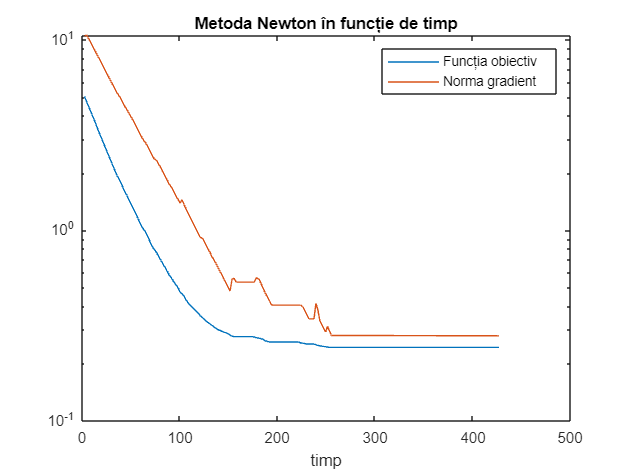


semilogy(v,fOb)
hold on 
semilogy(v,normG)
xlabel("timp")
legend("Funcția obiectiv","Norma gradient")
title("Metoda Newton în funcție de timp")


X=reshape(Xx(1:(n+1)*m),m,n+1)';
x=Xx((n+1)*m+1:(n+2)*m);

Scor de antrenare:

y_train=g(A_train*X)*x;
R2_train=1-(norm(e_train-y_train))^2/(norm(e_train-mean(e_train)))^2

R2_train = 0.5335

Scor de testare:

y_test=g(A_test*X)*x;
R2_test=1-(norm(e_test-y_test))^2/(norm(e_test-mean(e_test)))^2

R2_test = 0.4386

Pentru acest algoritm, am calculat în mod numeric gradientul si hessiana, calculul hessianei având o durată mai mare de calculare; algoritmul ajunge să termine de rulat după aproape 3 minute pentru 200 de iterații. La fel ca în cazul metodei gradient, funcția obiectiv converge, însă "treptele" care se pot observa pe graficul normei gradient indică momente în care nu progresează algoritmul, datorită "blocării" într-un punct de minim local.

Scorul R2 indică o proporție de 53% din date care sunt explicate de model, un rezultat ok. Însă, comparativ cu metoda Gradient, metoda Newton este mult mai lentă.

Deci, această problemă nefiind convexă, metoda Gradient este mai eficientă.

### **Funcții:**

**Funcția de activare:**

function y = g(z)
% functie de activare 
% nr 24 Functia TanhExp
y=z.*tanh(exp(z));
end

**Funcția obiectiv:**

function y=L(e,A,Xx,m)
[N,n]=size(A);
X=reshape(Xx(1:n*m),m,n)';
x=Xx(n*m+1:(n+1)*m);
y=(norm(g(A*X)*x-e))^2/2/N;
end

**Calcul Gradient Numeric:**

function y=gradNum(e,A,Xx,m)
[~,n]=size(A);
y=zeros(size(Xx));
for i=1:(n+1)*m
    h=1e-5;
    Xx1=Xx;
    Xx1(i)=Xx1(i)-h;
    Xx2=Xx;
    Xx2(i)=Xx2(i)+h;
    y(i)=(L(e,A,Xx2,m)-L(e,A,Xx1,m))/2/h;
end
end

**Calcul Hessiană Numeric:**

function Y=hessNum(e,A,Xx,m)
[~,n]=size(A);
Y=zeros(size(Xx,1));
for j=1:(n+1)*m
    h=1e-5;
    Xx1=Xx;
    Xx1(j)=Xx1(j)-h;
    Xx2=Xx;
    Xx2(j)=Xx2(j)+h;
    Y(:,j)=(gradNum(e,A,Xx2,m)-gradNum(e,A,Xx1,m))/2/h;
end
end